# Filters

## Introduction

**Filtering** in a broad sense is selecting portion(s) of data for some processing.

If we isolate a portion of data (e.g. audio, image, video) we can

- Remove it — *E.g.* Low Pass, High Pass *etc. filtering*

- Attenuate it — Enhance or diminish its presence, *E.g.* Equalisation, Audio Effects/Synthesis

- Process it in other ways — Digital Audio, *E.g.* Audio Effects/Synthesis

- **Much More Later --- plenty of examples.**

Filtering Examples:

- In many **multimedia** contexts this involves the removal of data from a signal — This is essential in almost all aspects of **lossy** multimedia data representations.

- **                    JPEG** **Image** Compression

- **                    MPEG** **Video** Compression

- **                    MPEG**  **Audio** Compression

- In **Digital Audio** we may wish to determine a range of frequencies we wish the enhance or diminish to equalise the signal, *e.g.*:

- **                    Tone** — Treble and Bass — **Controls**

- **                    Equalisation (EQ)**

- **                    Synthesis** — Subtractive Synthesis, EQ in others.

### How can we filter a Digital Signal?

There are two basic ways to Filter:

- Temporal Domain — *E.g.* Sampled (PCM) Audio

- Frequency Domain — Analyse frequency components in signal. 

We will look at filtering in the **frequency space** very soon, but first we consider filtering in the **temporal domain** via **impulse responses**.

## Temporal Domain Filters

We will look at:

- **IIR Systems**: Infinite impulse response systems

- **FIR Systems**: Finite impulse response systems

### Infinite Impulse Response (IIR) Systems

A simple Example IIR Filter:

- The **algorithm** is represented by the **difference equation**:         


$$y(n) = x(n) - a_1. y(n-1) - a_2.y(n-2)$$


- This produces the following **signal flow graph**

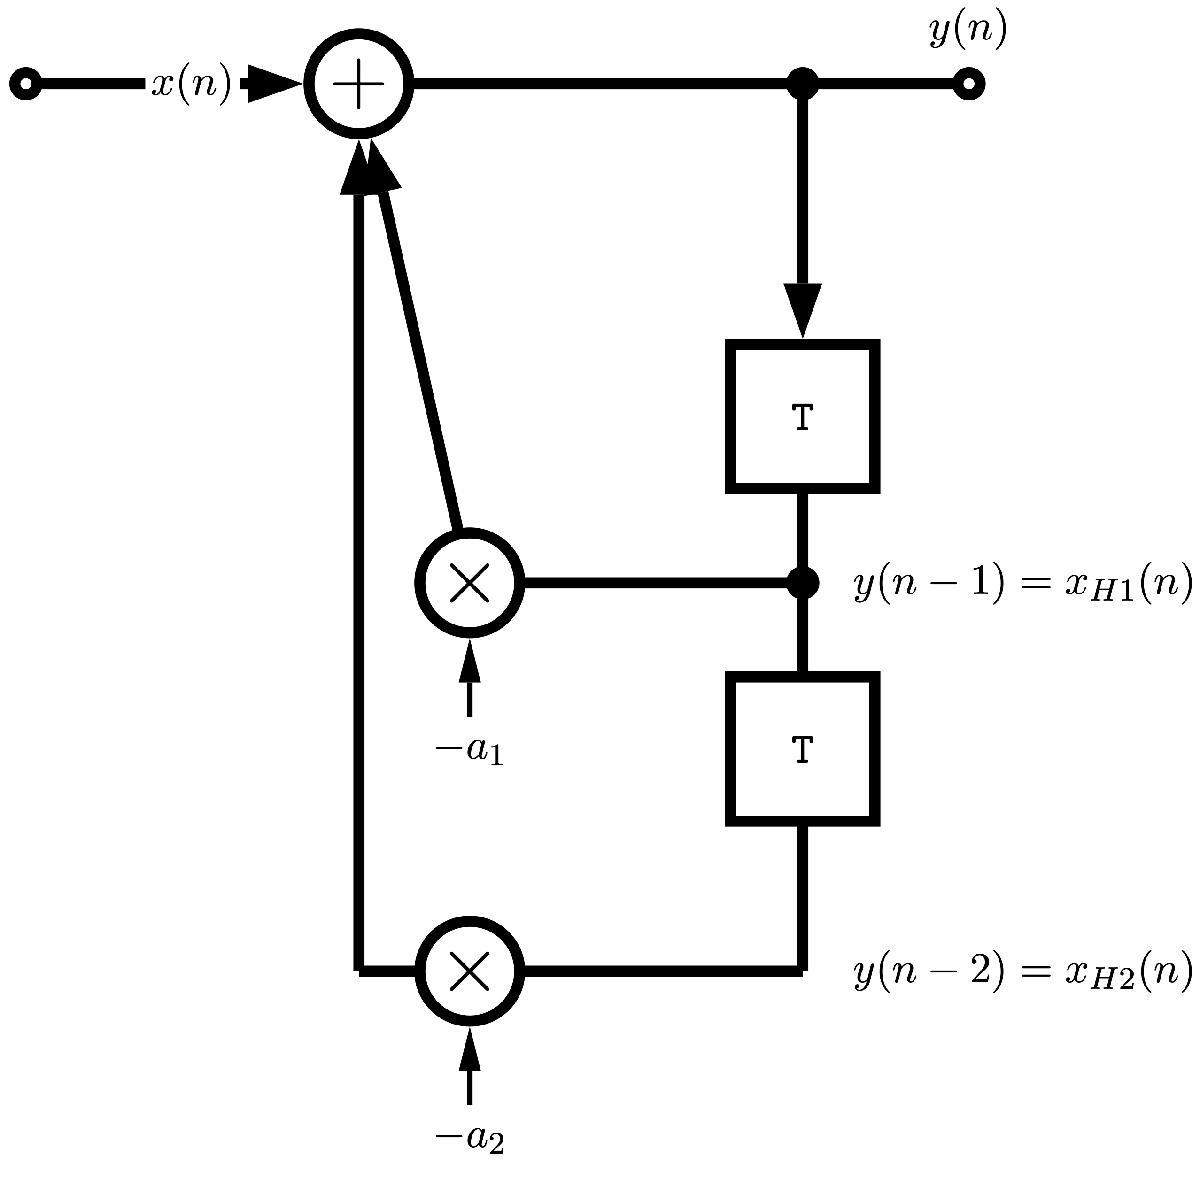

*** IIR Filter Explained***

 The following happens:

- The **output signal** $y(n)$ is ***fed back*** through a **series** of **delays**

- Each **delay** is **weighted**

- Each fed back **weighted delay** is **summed** and passed to **new** **output**.

- Such a **feedback** system is called a **recursive system**

**A Complete IIR System**

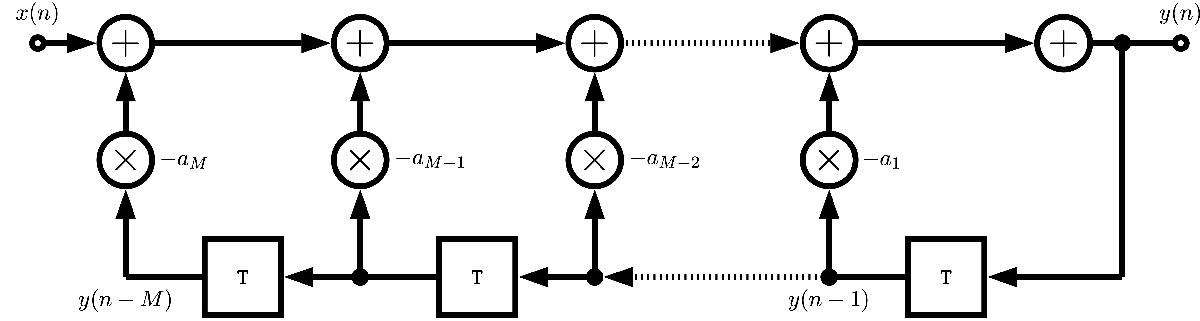

**The Complete IIR Algorithm**

Here we extend the simple IIR: 

- The **input** delay line up to  $N-1$ elements and 

- The  **output** delay line by  $M$ elements.

- We can represent the IIR system algorithm by the difference 

- equation: 

                    
$$y(n) = x(n) - \sum_{k=1}^M a_k\:y(n-k)$$


### Finite Impulse Response (FIR) Systems

FIR system's are slightly differnet in construction — there is **no** **feedback loop **but there is a** feed forward loop.**

A simple FIR system can be described as follows: 


$$y(n) = b_0 x(n) + b_1 x(n-1) + b_2 x(n-2)$$


- The **input** is **fed through** **delay elements**

- **Weighted sum** of **delays** gives $y(n)$

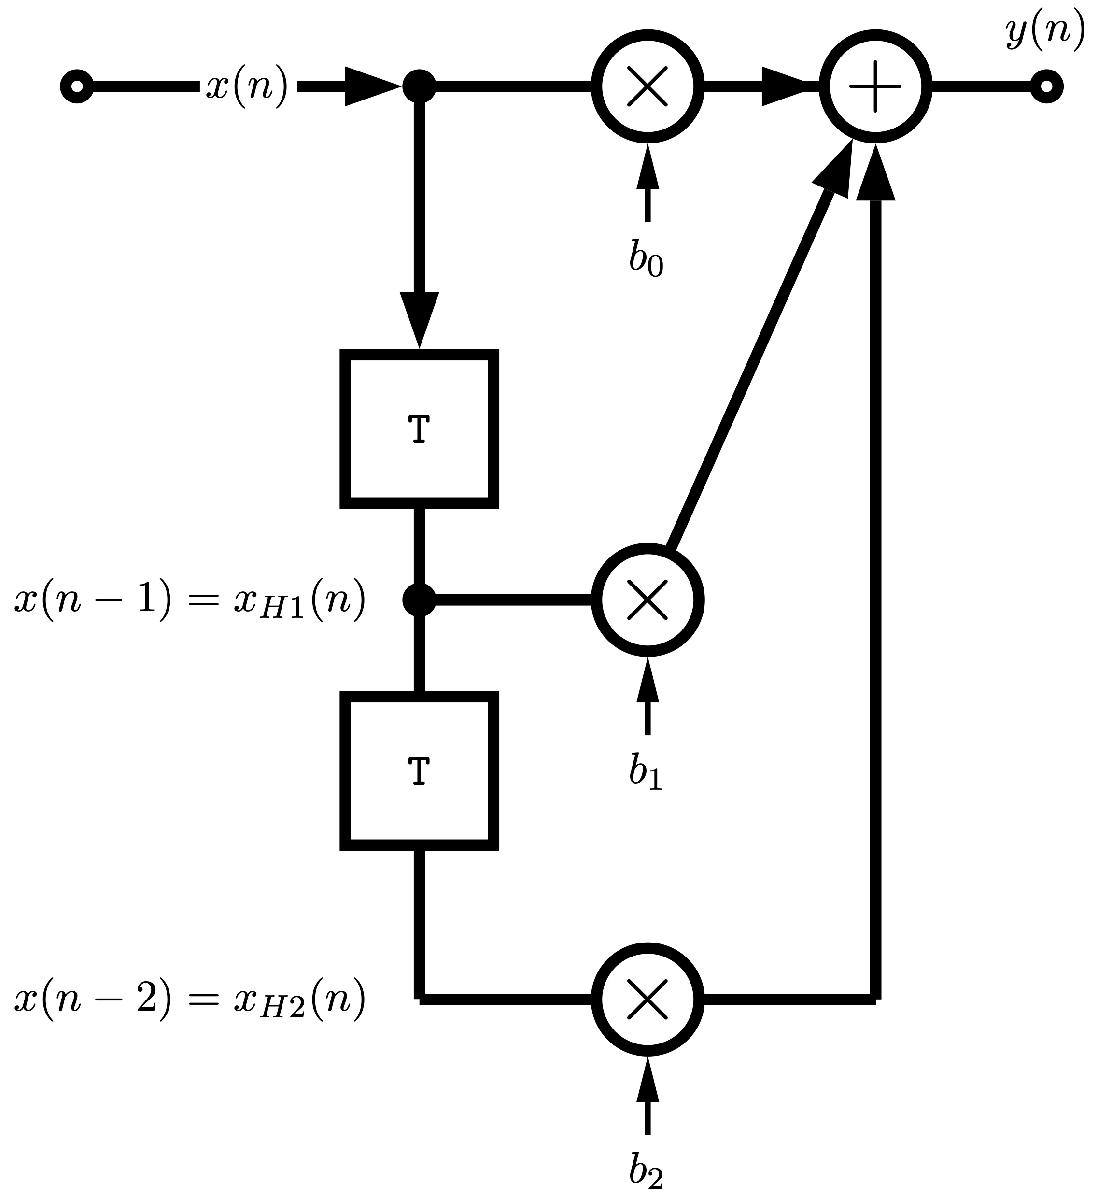

A Complete FIR System:

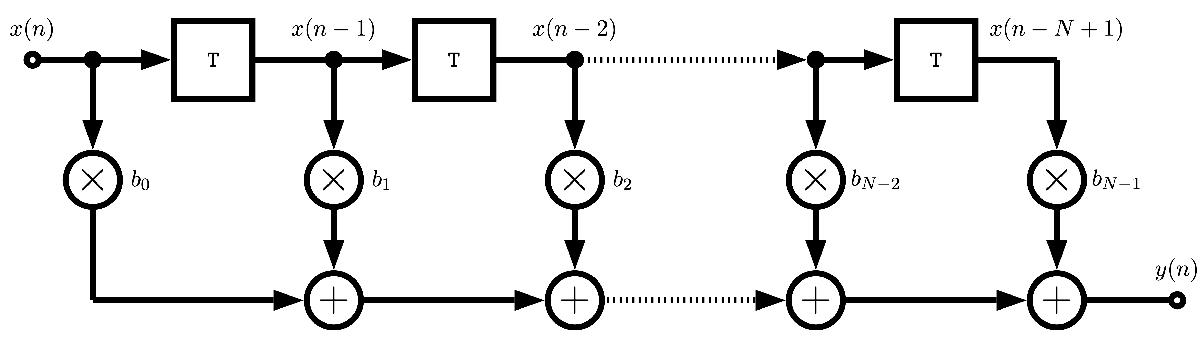

To develop a more complete FIR system we need to add $N-1$ **feed forward** **delays**

We can describe this with the algorithm: 

                            
$$y(n) = \sum_{k=0}^{N-1} b_k \: x(n-k)$$


### Practical Filtering with the IIR/FIR

We can **combine** both the IIR/FIR to create more advanced filters:

We simple "glue" both filter types togthers.

We now have **two** ***filter banks*** defined by vectors: $A = {a_k}$, $B = {b_k}$.

These can be applied in a *sample-by-sample* algorithm:

- MATLAB provides a generic `filter(B,A,X)` function which filters the data in vector `X` with the filter described by vectors `A` and  `B` to create the filtered data `Y`.  

The filter is of the standard difference equation form:

                   
$$a(1)*y(n) =  b(1)*x(n) + b(2)*x(n-1) + ... + b(nb+1)*x(n-nb)\\~~~~~~~~~~~ - a(2)*y(n-1) - ... - a(na+1)*y(n-na)$$
 

**Note:**

- If a(1) is **not equal** to **1**, filter **normalizes** (divides throughout) the filter coefficients by a(1). If **a(1) equals 0**, `filter()`  **returns** an **error**

**For more info see**

showDoc = 0;
if showDoc
    doc filter;
end

or

showHelp = 1;

if showHelp
   help filter;
end

### Creating Filters

How do you create Filter banks `A` and  `B? `A few ways (depending on application)

- Filter banks can be created manually  This is more for specialist areas (e.g. specialst devices of signals) where bespoke filters may need to be crafted. *This is not that applicable to classical mutlimedia signals that we use*. Nevertheless, it is instructive to see how one can do this — *See next example* and  *Equalisation example* later.

- MATLAB can provide some predefined filters:

-                    Many standard filters provided by MATLAB, these are commonly applied in many applications **not just **mutlimedia signals.

-                    See also `help filter`, online MATLAB `doc`**s** and lab classes (see above).

### Filtering with IIR/FIR: Simple Manual Filter Creation Example

#### Rolling your own filter from scratch

The MATLAB file [IIRdemo.m](http://users.cs.cf.ac.uk/Dave.Marshall/CM2208/MATLAB/DSP/DSP_EGs/IIRdemo.m) sets up the filter banks as follows:

fg=4000; 
fa=48000; 
k=tan(pi*fg/fa);

b(1)=1/(1+sqrt(2)*k+k^2);
b(2)=-2/(1+sqrt(2)*k+k^2); 
b(3)=1/(1+sqrt(2)*k+k^2); 

a(1)=1; 
a(2)=2*(k^2-1)/(1+sqrt(2)*k+k^2); 
a(3)=(1-sqrt(2)*k+k^2)/(1+sqrt(2)*k+k^2);

The exact derivation of meaning of the above filter is beyond the scope of this simple illustration. Whilst it is important to craft specific values for `a` and `b` (otherwise the filter will not work work at all, you could easily create destructive feedback loops, for example). For more details, consult the DAFX text book.

How to apply this filter back via a difference equation:

- You could try by hand, [IIRdemo.m](http://users.cs.cf.ac.uk/Dave.Marshall/CM2208/MATLAB/DSP/DSP_EGs/IIRdemo.m) cont,:

% Initialization of state variables
xh1=0;xh2=0;
yh1=0;yh2=0;

% Input signal: unit impulse
N=20;  % length of input signal
x(1:N)=0;
x(1)=1;

for n=1:N 
     y(n)=b(1)*x(n) + b(2)*xh1 + b(3)*xh2 - a(2)*yh1 - a(3)*yh2; 
     xh2=xh1;xh1=x(n); 
     yh2=yh1;yh1=y(n); 
end
 
figure;
% Plot results
subplot(2,1,1)
stem(0:1:length(x)-1,x,'.');axis([-0.6 length(x)-1 -1.2 1.2]);
xlabel('n \rightarrow');ylabel('x(n) \rightarrow');
subplot(2,1,2)
stem(0:1:length(x)-1,y,'.');axis([-0.6 length(x)-1 -1.2 1.2]);
xlabel('n \rightarrow');ylabel('y(n) \rightarrow');

#### Use `filter` with own filter bank

- Use MATLAB `filter()` function:

-                   This is geneally *far more ****preferable***: This generalises to **any length filter **and is less code to type**!**

yf = filter(b,a,x);

figure;
% Plot results
subplot(2,1,1)
stem(0:1:length(x)-1,x,'.');axis([-0.6 length(x)-1 -1.2 1.2]);
xlabel('n \rightarrow');ylabel('x(n) \rightarrow');
subplot(2,1,2)
stem(0:1:length(x)-1,yf,'.');axis([-0.6 length(x)-1 -1.2 1.2]);
xlabel('n \rightarrow');ylabel('yf(n) \rightarrow');

#### MATLAB built in filters

MATLAB provides a few built-in functions to create ready made filter parameter $A$ and $B$:

Some common MATLAB Filter Bank Creation Functions *E.g*: `butter, buttord, besself, cheby1, cheby2, ellip`.

See `help` or `doc` appropriate function.

showHelp = 1;

if showHelp
    help butter;
end

or

showDoc = 0;
if showDoc
    doc butter;
end

We'll see some pratical example uses shortly, but here is a quick example:

% Design a 6th-order lowpass Butterworth filter with a cutoff frequency of 300 Hz, which, 
% for data sampled at 1000 Hz, corresponds to  rad/sample. 
% 
% Plot its magnitude and phase responses. 
% Use it to filter a 1000-sample random signal.

fc = 300;
fs = 1000;

[b,a] = butter(6,fc/(fs/2));
freqz(b,a)

dataIn = randn(1000,1);
dataOut = filter(b,a,dataIn);

**Note**: We will study the **Butterworth** filter in **more detail** later

## Applications of Filtering 

There are numerous examples of Filtering in DSP:

- Noise Removal

- Signal Analysis

- Audio Synthesis

- Audio Effects

- Many more ....

Two Examples

- **Subtractive Synthesis**

- **Equalisation** — Tone control

### Subtractive Synthesis

**Basic Idea**: Subtractive synthesis is a method where we subtract ***overtones*** from a sound via filtering.

While subtractive synthesis can be applied to any source audio signal, the sound most commonly associated with the technique is that of analog synthesizers of the 1960s and 1970s, in which the harmonics of simple waveforms  (but still relatively harmonically rich) such as sawtooth, pulse or square waves are attenuated with a voltage-controlled resonant ***low-pass filter***. Many digital, virtual analog and software synthesizers use subtractive synthesis, sometimes in conjunction with other methods of sound synthesis – we'll see some examples of these in due course.

- First Example: [Vocoder](https://en.wikipedia.org/wiki/Vocoder#History) — talking robot (1939).

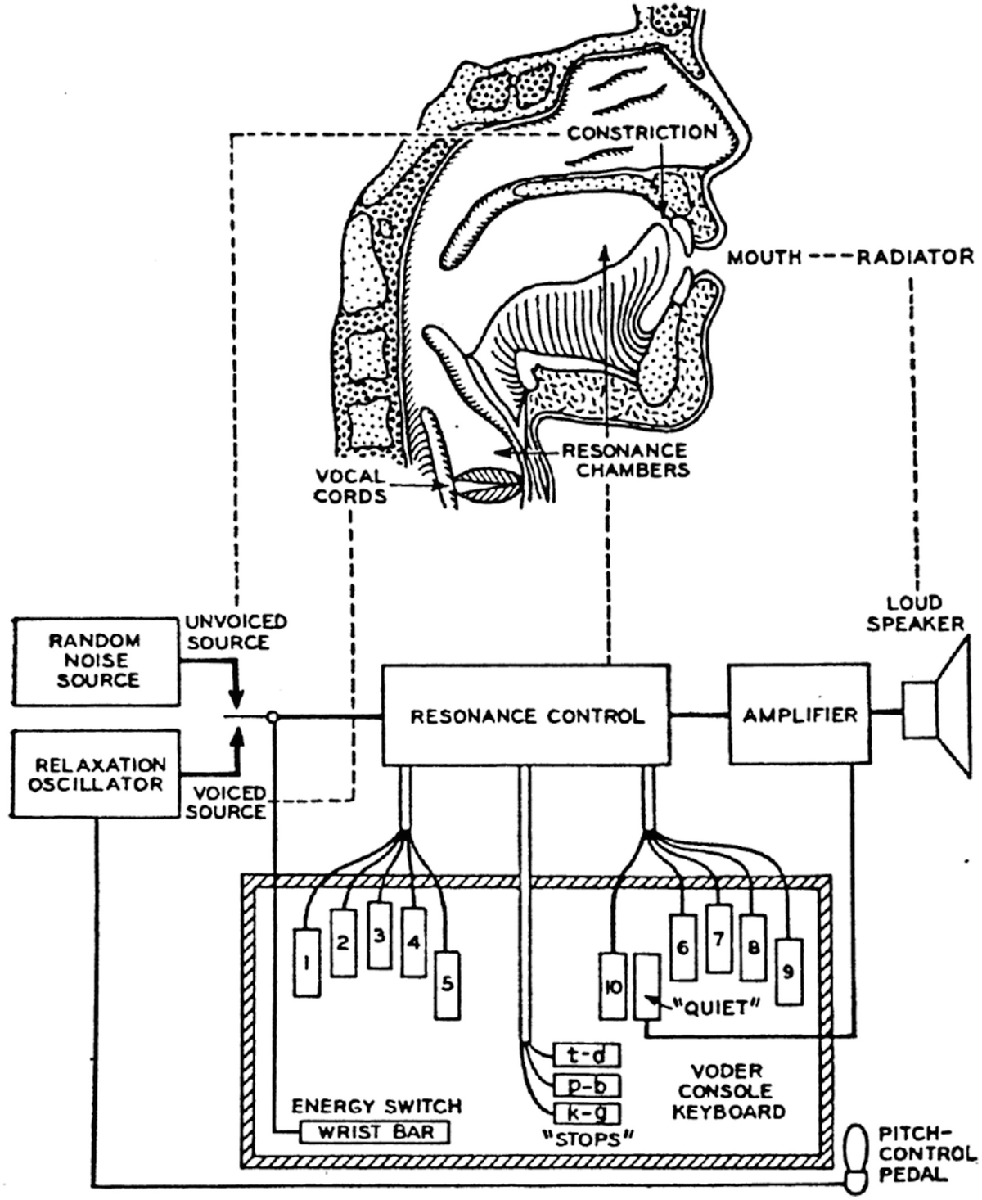

- Subtractive Synthesis was popularised with [Moog Synthesisers](https://en.wikipedia.org/wiki/Moog_synthesizer) 1960-1970s

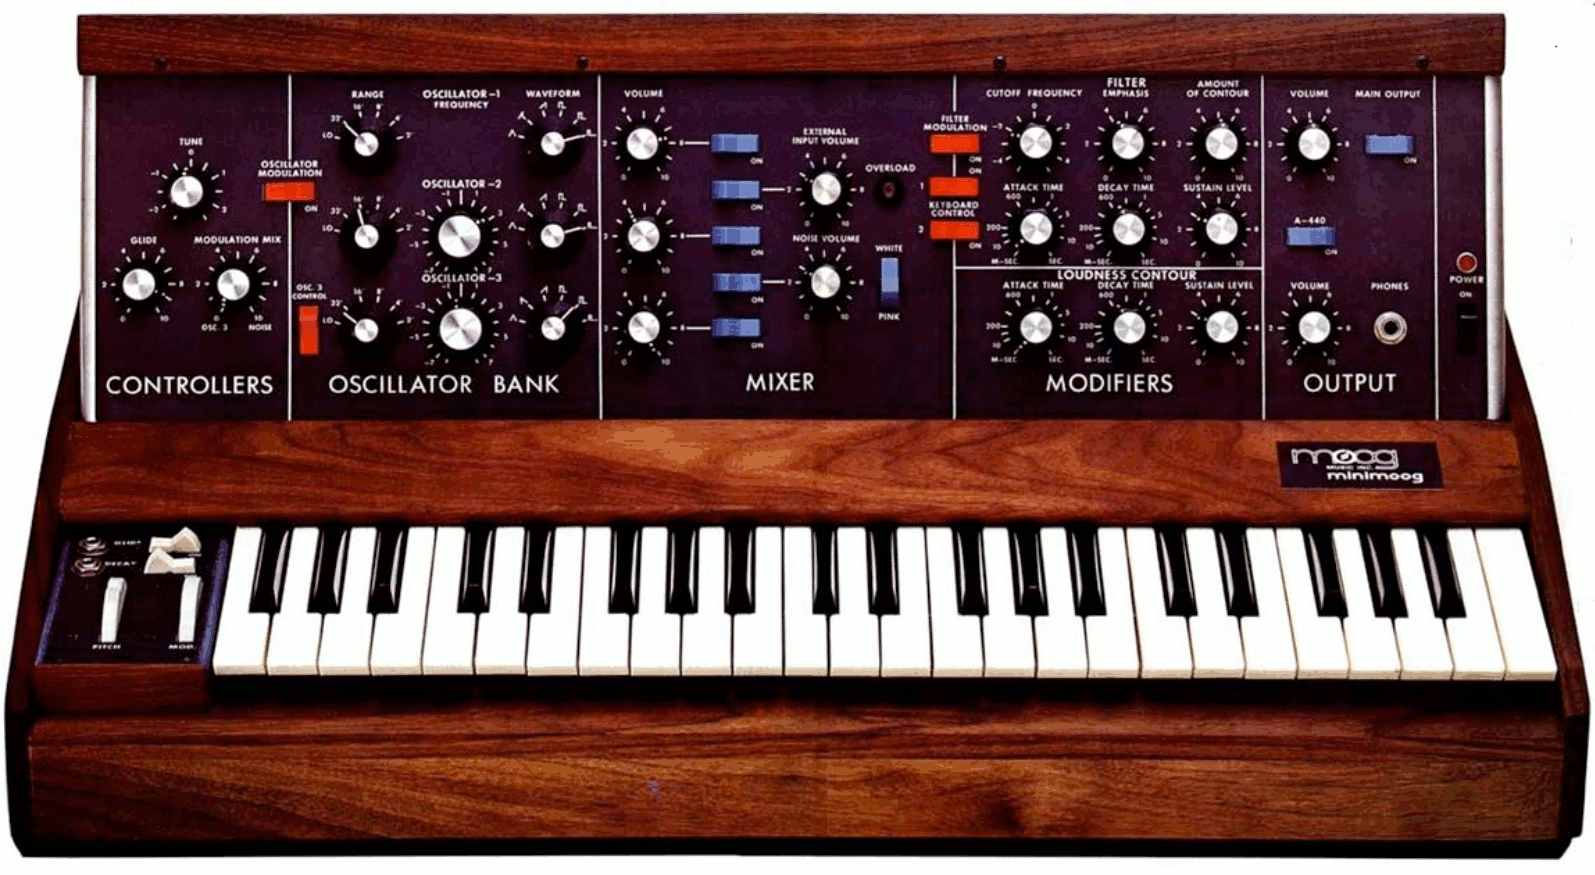

See this youtube video of a Moog in action: [Moog Modular](https://www.youtube.com/watch?v=n3K_fZDvINs), [Mini-Moog](https://www.youtube.com/watch?v=WY2AeD0Tn4Y) (See also [History of Moog](https://www.youtube.com/watch?v=sLx_x5Fuzp4))

- [The Moog in popular music](https://www.youtube.com/watch?v=NlbUPXlOYSo)

See also the video demonstration in a lecture, by me, of a virtual analog Moog

#### Subtractive Synthesis: Simple Example Illustrations

**Simulating a bowed string**

- Take the output of a sawtooth generator

- Use a low-pass filter to dampen its higher partials generates a more natural approximation of a bowed string instrument than using a sawtooth generator alone.

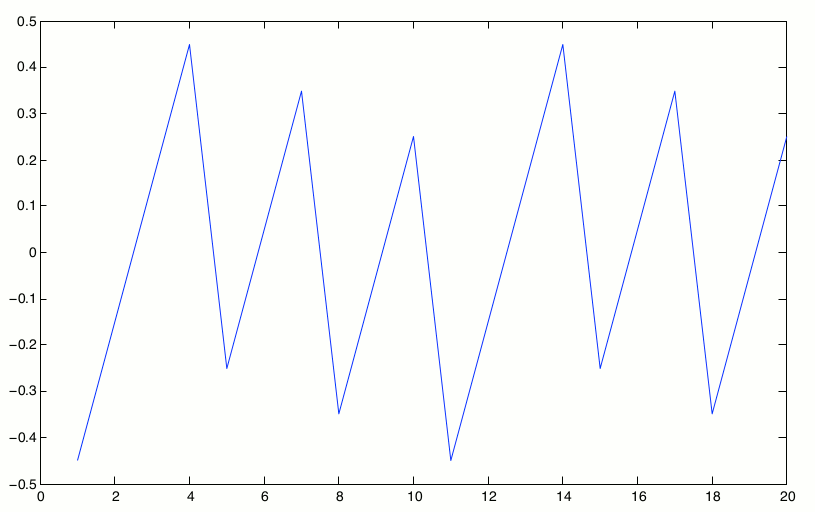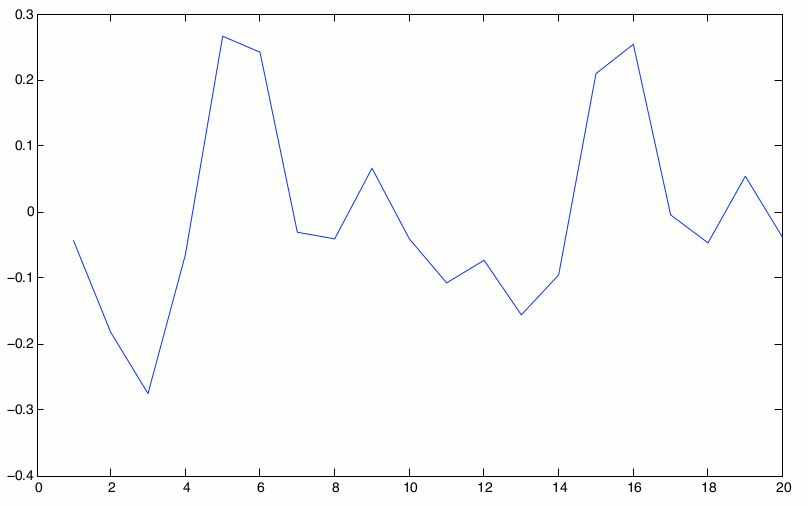

- [subtract_synth.m](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Synth/subtract_synth.m) MATLAB Code Example (analysed later on the in the lecture).

#### Subtractive Synthesis: A Human Example

**We can regard the way in which humans make noises, even speak, as subtractive synthesis:**

**- Oscillator**— the vocal cords act as the sound source and...

**- Filter**— the mouth and throat modify the sound.

- Saying or singing “ooh” and “aah” (at the same pitch.)

- Vocal chords are generating pretty much the same raw, rich in harmonic sound. Difference between the two comes from the filtering which we apply with the mouth and throat.

- Change of mouth shape varies the **cutoff frequency** of the filter, so removing (**subtracting**) some of the harmonics.

- The “aah” sound has most of the original harmonics still **present**,

- The “ooh” sound has most of them **removed** (or to be more precise, reduced in amplitude.)

**A sweeping filter**

 **"ooh"s to "aah"s again**

- By gradually changing from "ooh" to "aah" and back again – simulate the "sweeping filter" effect

- Effect widely used in electronic music

- Basis of the "wahwah" guitar effect, so named for obvious reasons.

- We will see how we produce this effect in MATLAB code shortly.

#### Subtractive Synthesis: One More Human Example **Making Aeroplane or Wind Noises**

 **Make a "ssh" sound — white noise**

- Now "synthesise" a "jet plane landing" sound

- Should mostly by use mouth shape to filter the white noise into pink noise by removing the higher frequencies.

- The same technique (filtered white noise) can be used to electronically synthesise the sound of ocean waves and wind,

- Used in early drum machines to create snare drum and other percussion sounds.

### Subtractive Synthesis Example: Using MATLAB Filter 

This example for studying subtractive synthesis uses the `butter()` and `filter()` MATLAB functions (It is basically the solution for a question in Week 1's Lab sheet ([CM3106_Lab_1_1_and_1_2_DSP_Filters.mlx](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/MATLAB_LIVE_SCRIPTS/CM3106_Lab_1_1_and_1_2_DSP_Filters.mlx)):

% simple low pass filter example of subtractive synthesis
Fs = 22050;


The supporting function, [synth.m](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Synth/synth.m), generates waveforms as we have seen earlier in this tutorial.

y = synth(440,2,0.9,22050,'saw');

% Play Raw Sawtooth? Y/[N]?
PlayRawSawtooth = 1;

if PlayRawSawtooth
  figure(1)
plot(y(1:440));
sound(y,Fs);
end

**Note:** the sawtooth waveform generated here has a non-linear up slope:

This is created with (see [synth.m](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Synth/synth.m) right click on the function name and open function to see the code):

`fix()` rounds the elements of `X` to the nearest integers towards zero.

This form of sawtooth sounds slightly less harsh and is more suitable for audio synthesis purposes:  emulates – vitual analog – how sawtooths are implemented in analog electronics: essentially charging and dicharging capacitors, which have a non-linear response time.

Next, we create some basic filters, two are illustrated below, but other filters can be used: These can be differen filter classes (e.g. FIR/IIR, Chebyshev, Bessel) and types (e.g. bandpass, comb, high pass) (try a few others yourself):

% make lowpass filter two example Butterworth filters of varying order 

[B, A] = butter(1,0.04, 'low');
yf = filter(B,A,y);

[B, A] = butter(4,0.04, 'low');
yf2 = filter(B,A,y);

% Play Low Pass Filtered (Low order) ? Y/[N]
PlayLowPassFilteredLowOrder = 1;

if PlayLowPassFilteredLowOrder
figure(2)
plot(yf(1:440));
sound(yf,Fs);
end


% Play Low Pass Filtered (Higher order)? Y/[N]
PlayLowPassFilteredHigherOrder = 1;

if PlayLowPassFilteredHigherOrder
    figure(3)
plot(yf2(1:440));
sound(yf2,Fs);
end


%Plot All Figures? Y/[N]
PlotAllFigures = 1;

if PlotAllFigures
figure(4)
plot(y(1:440));
hold on
plot(yf(1:440),'r+');
plot(yf2(1:440),'g-');
end
hold off;

Compare the sounds again:

out_y = y;
sound(out_y,Fs);
 

So in essence Subtractive Synthesis is a basic example of filtering.

### Basic Digital Audio Filtering Effects: Equalisers

Filters **Filters** by definition **remove/attenuate** audio from the spectrum above or below some cut-off frequency.

- For many audio applications this a little too restrictive

Equalisers **Equalisers**, by contrast, **enhance/diminish** certain frequency bands whilst leaving others **unchanged**:

- Built using a series of *shelving* and *peak* filters 

- First or second-order filters usually employed.

####  Shelving and Peak Filters

Two Special Classes of Filters:

Shelving Filter:

**Boos**t or **cut** the **low** or **high frequency bands** with a **cut-off frequency**, $F_c$ and gain $G$:

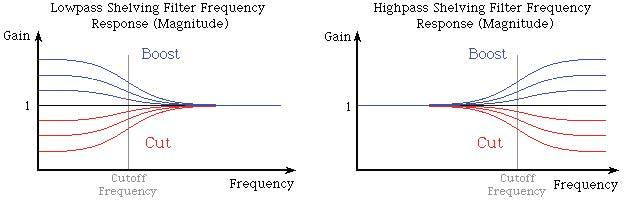

Peak Filter: 

**Boost** or **cut** **mid-frequency** bands with a **cut-off frequency**, $F_c$, a **bandwidth**, $f_b$ and **gain** $G$:

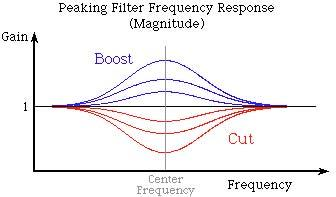

## 1st Order Shelving Filter

A First-order Shelving Filter: Transfer function: **blue** 

$H(z) = 1 + (1\pm A(z))$    where *Low Pass Filter is * + or High Pass Filter is -

$A(z)$ is a first-order **allpass** filter — it passes all frequencies but modifies phase:  

$A(z) = \frac{z^{-1} + a_{B/C}}{1+  a_{B/C}z^{-1}$    B=Boost, C=Cut

which leads the following **algorithm**/**difference equation**: 


$$y_1(n)  =  a_{B/C} x(n) + x (n-1) - a_{B/C}y_1(n-1)$$


 
$$y(n)  =  \frac{H_0}{2} (x(n) \pm y1(n)) + x(n)$$
 

Shelving Filter Parameters: The **gain**, $G$, in dB can be adjusted accordingly:  

$H_0 = V_0 -1$  where $V_0 = 10^{G/20}$

and the cut-off frequency for  **boost**, $a_B$, or  **cut**, $a_C$ are given by:


$$a_B  =  \frac{tan(2\pi f_c/f_s) - 1}{tan(2\pi f_c/f_s) + 1}$$



$$a_C  =  \frac{tan(2\pi f_c/f_s) - V_0}{tan(2\pi f_c/f_s) - V_0}$$


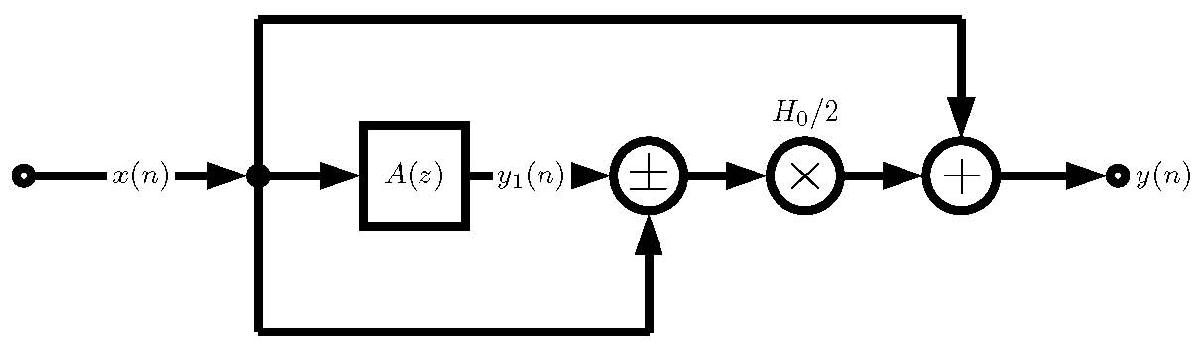

where $A(z)$ is given by:

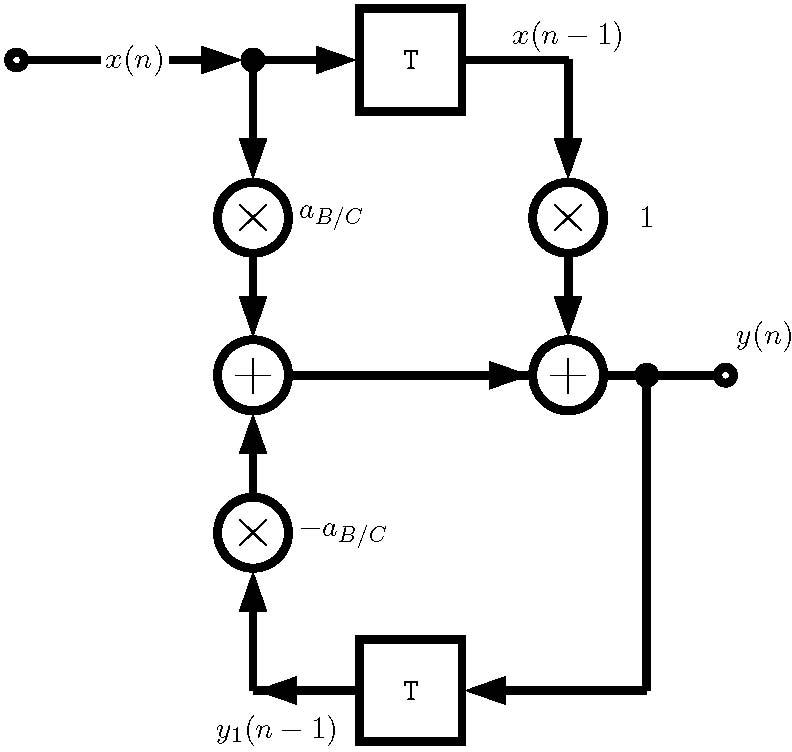

## 2nd-order Peak Filter

A 2nd-order Peak Filter Transfer function: 


$$H(z) = 1 + \frac{H_0}{2} (1 - A_2(z))$$


where $A_2(z)$ is a **second-order** **allpass** filter: 


$$A(z) = \frac{-a_B + (d-da_B)z^{-1} + z^{-2}}{1 + (d-da_B)z^{-1} + a_B z^{-2}}$$
 

which leads the following algorithm/difference equation: 


$$y_1(n)  =  a_{B/C} x(n) + d(1- a_{B/C})x (n-1) +x(n-2) \\\:\:\:\:\:\:\:\:\:\:\:\:\:\:\:-d(1-a_{B/C}) y_1(n-1) + a_{B/C} y_1(n-2)$$
 


$$y(n)  =  \frac{H_0}{2} (x(n) - y_1(n)) + x(n)$$


The **center/cut-off frequency**, $d$, is given by: 


$$d = -cos(2\pi f_c/f_s)$$


The $H_0$ by relation to the gain, $G$, as before:  

$H_0 = V_0 -1$  where $V_0 = 10^{G/20}$

and the bandwidth, $f_b$ is given by the limits for  **boost**, $a_B$, or  **cut**, $a_C$ are given by:


$$a_B  =  \frac{tan(2\pi f_b/f_s) - 1}{tan(2\pi f_b/f_s) + 1}$$
 


$$a_C = \frac{tan(2\pi f_b/f_s) - V_0}{tan(2\pi f_b/f_s) - V_0}$$


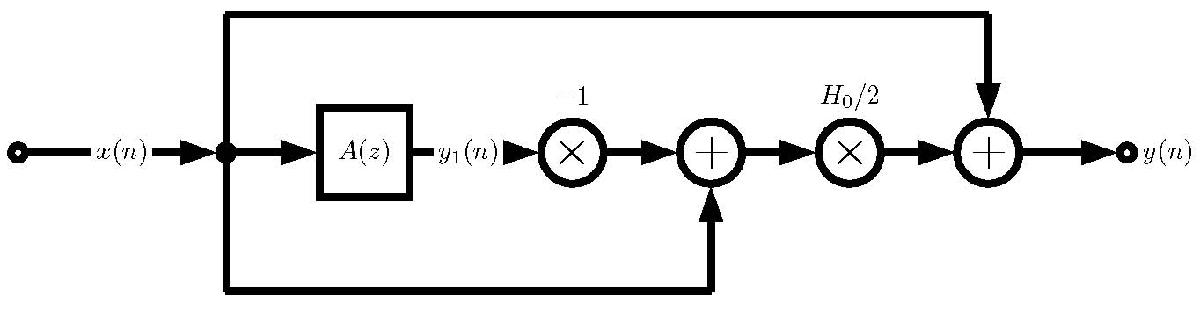

where $A(z)$ is given by:

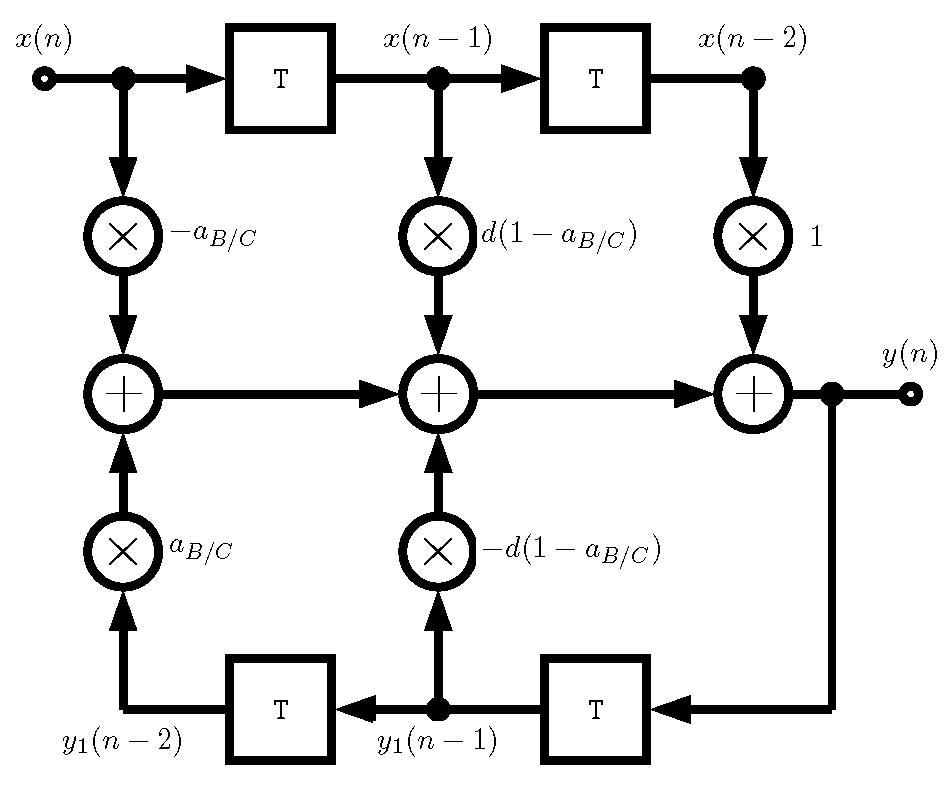

## MATLAB Shelving Filter EQ Example Code

[shelving.m](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Digital_Audio_FX/shelving.m): implements a basic filter confiuration which we then call with a few parameter settings:

### A few Examples of Selving EQ Function calls

#### Bass Shelfing Boost EQ

An example of Bass Shelfing use is given by: [shelving_eg.m](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Digital_Audio_FX/shelving_eg.m) 

% read the sample waveform
filename = 'acoustic.wav';
if exist(filename) == 0
    % read file from URL
    [x,Fs] = webread('http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Digital_Audio_FX/acoustic.wav');
else
    [x,Fs] = audioread(filename);
end

%set Parameters for Shelving Filter
% Change these to experiment with filter

G = 4;
fcb = 300;
Q = 3;
type = 'Bass_Shelf';

[b, a] = shelving(G, fcb, Fs, Q, type);


yb = filter(b, a, x);


% write output wav files
%audiowrite('out_bassshelf.wav', yb, Fs);

% plot the original and equalised waveforms

figure(1)
hold on
plot(yb,'b');
plot(x,'r');
title('Bass Shelf Boost Filter Equalised Signal (Blue - Eq., Red - original)');
hold off;

% Play Bass Shelf EQ
sound_choice = x;

sound(sound_choice,Fs);

 

#### Treble Shelf Boost EQ Example:

fct = 600;
Q = 3;
type = 'Treble_Shelf';


[b, a] = shelving(G, fct, Fs, Q, type);


yt = filter(b, a, x);


figure(2)
hold on
plot(yt,'g');
plot(x,'r');
title('Treble Shelf Boost Filter Equalised Signal (Green - Eq., Red - original)');
hold off;

% Play Treble Shelf EQ
sound_choice = yt;

sound(sound_choice,Fs);

 

% write output wav files
%audiowrite('out_treblehelf.wav', yt, Fs);

Compare the EQ's Audio:

% Play Treble Shelf EQ
sound_choice = yb;

sound(sound_choice,Fs);

 

#### Now do the cut: 

Set the Gain, $G$ to be $< 0$ and implement a bass and treble cut. Also vary the cut off frequency, $f_c$ and the $Q$ of the flter:

G = 2.3;
fct = 580;
Q = 7;
type = 'Bass_Shelf';

 

[b, a] = shelving(G, fct, Fs, Q, type);


y = filter(b, a, x);


figure(2)
hold on
plot(y,'g');
plot(x,'r');
title('Equalised Signal (green - Eq., Red - original)');
hold off;

% Play EQ v. Original Audio
sound_choice = y;

sound(sound_choice,Fs);

 

## Further Reading

**DAFX: Digital Audio Effects, **Udo Zolzer, John Wiley and Sons Ltd , 2002 

(ISBN-13: 978-0471490784) 

- *Excellent coverage of audio signal processing effects and synthesis plus a lot more* 

- **All MATLAB examples** 

- **Copies in library**

- [Online version available in library.](https://librarysearch.cardiff.ac.uk/primo-explore/fulldisplay?docid=44CAR_ALMA51125638430002420&context=L&vid=44WHELF_CAR_VU1&lang=en_US&search_scope=CSCOP_EVERYTHING&adaptor=Local%20Search%20Engine&tab=searchall@cardiff&query=any,contains,DAFX&offset=0)

**Audio Synthesis**— [CM3106 Module Notes](http://www.cs.cf.ac.uk/Dave/Multimedia/PDF/05_Audio_Synthesis.pdf )

**Audio Effects**— [CM3106 Module Notes](http://www.cs.cf.ac.uk/Dave/Multimedia/PDF/07_Audio_Effects.pdf)

See **Lab Class** Exercises

## Supporting Functions

function y=synth(freq,dur,amp,Fs,type)
% y=synth(freq,dur,amp,Fs,type)
%
% Synthesize a single note
%
% Inputs:
%  freq - frequency in Hz
%  dur - duration in seconds
%  amp - Amplitude in range [0,1]
%  Fs -  sampling frequency in Hz
%  type - string to select synthesis type
%         current options: 'fm', 'sine', or 'saw'
%
%---------------------------------------------------------------
% Subversion Revision: 12 (2006-01-24)
%
% This software can be used freely for non-commerical use.
% Visit http://www.kenschutte.com/software for more
%   documentation, copyright info, and updates.
%---------------------------------------------------------------

    if nargin<5
      error('Five arguments required for synth()');
    end
    
    N = floor(dur*Fs);
    n=0:N-1;
    if (strcmp(type,'sine'))
      y = amp.*sin(2*pi*n*freq/Fs);
    
    elseif (strcmp(type,'saw'))
    
      T = (1/freq)*Fs;     % period in fractional samples
      ramp = (0:(N-1))/T;
      y = ramp-fix(ramp);
      y = amp.*y;
      y = y - mean(y);
    
    elseif (strcmp(type,'fm'))
    
      t = 0:(1/Fs):dur;
      envel = interp1([0 dur/6 dur/3 dur/5 dur], [0 1 .75 .6 0], 0:(1/Fs):dur);
      I_env = 5.*envel;
      y = envel.*sin(2.*pi.*freq.*t + I_env.*sin(2.*pi.*freq.*t));
      
    else
      error('Unknown synthesis type');
    end
    
    % smooth edges w/ 10ms ramp
    if (dur > .02)
      L = 2*fix(.01*Fs)+1;  % L odd
      ramp = bartlett(L)';  % odd length
      L = ceil(L/2);
      y(1:L) = y(1:L) .* ramp(1:L);
      y(end-L+1:end) = y(end-L+1:end) .* ramp(end-L+1:end);
    end
end


   [shelving.m](http://users.cs.cf.ac.uk/Dave.Marshall/Multimedia/Lecture_Examples/Digital_Audio_FX/shelving.m):

function [b, a]  = shelving(G, fc, fs, Q, type)
%
% Derive coefficients for a shelving filter with a given amplitude and
% cutoff frequency.  All coefficients are calculated as described in
% Zolzer's DAFX book (p. 50 -55).
%
% Usage:     [B,A] = shelving(G, Fc, Fs, Q, type);
%
%            G is the logrithmic gain (in dB)
%            FC is the center frequency
%            Fs is the sampling rate
%            Q adjusts the slope be replacing the sqrt(2) term
%            type is a character string defining filter type
%                 Choices are: 'Bass_Shelf' or 'Treble_Shelf'


%Error Check
if((strcmp(type,'Bass_Shelf') ~= 1) && (strcmp(type,'Treble_Shelf') ~= 1))
    error(['Unsupported Filter Type: ' type]);
end

K = tan((pi * fc)/fs);
V0 = 10^(G/20);
root2 = 1/Q; %sqrt(2)

%Invert gain if a cut
if(V0 < 1)
    V0 = 1/V0;
end

%%%%%%%%%%%%%%%%%%%%
%    BASE BOOST
%%%%%%%%%%%%%%%%%%%%
if(( G > 0 ) && (strcmp(type,'Bass_Shelf')))
    
    b0 = (1 + sqrt(V0)*root2*K + V0*K^2) / (1 + root2*K + K^2);
    b1 =             (2 * (V0*K^2 - 1) ) / (1 + root2*K + K^2);
    b2 = (1 - sqrt(V0)*root2*K + V0*K^2) / (1 + root2*K + K^2);
    a1 =                (2 * (K^2 - 1) ) / (1 + root2*K + K^2);
    a2 =             (1 - root2*K + K^2) / (1 + root2*K + K^2);
    
    %%%%%%%%%%%%%%%%%%%%
    %    BASE CUT
    %%%%%%%%%%%%%%%%%%%%
elseif (( G < 0 ) && (strcmp(type,'Bass_Shelf')))
    
    b0 =             (1 + root2*K + K^2) / (1 + root2*sqrt(V0)*K + V0*K^2);
    b1 =                (2 * (K^2 - 1) ) / (1 + root2*sqrt(V0)*K + V0*K^2);
    b2 =             (1 - root2*K + K^2) / (1 + root2*sqrt(V0)*K + V0*K^2);
    a1 =             (2 * (V0*K^2 - 1) ) / (1 + root2*sqrt(V0)*K + V0*K^2);
    a2 = (1 - root2*sqrt(V0)*K + V0*K^2) / (1 + root2*sqrt(V0)*K + V0*K^2);
    
    %%%%%%%%%%%%%%%%%%%%
    %   TREBLE BOOST
    %%%%%%%%%%%%%%%%%%%%
elseif (( G > 0 ) && (strcmp(type,'Treble_Shelf')))
    
    b0 = (V0 + root2*sqrt(V0)*K + K^2) / (1 + root2*K + K^2);
    b1 =             (2 * (K^2 - V0) ) / (1 + root2*K + K^2);
    b2 = (V0 - root2*sqrt(V0)*K + K^2) / (1 + root2*K + K^2);
    a1 =              (2 * (K^2 - 1) ) / (1 + root2*K + K^2);
    a2 =           (1 - root2*K + K^2) / (1 + root2*K + K^2);
    
    %%%%%%%%%%%%%%%%%%%%
    %   TREBLE CUT
    %%%%%%%%%%%%%%%%%%%%
    
elseif (( G < 0 ) && (strcmp(type,'Treble_Shelf')))
    
    b0 =               (1 + root2*K + K^2) / (V0 + root2*sqrt(V0)*K + K^2);
    b1 =                  (2 * (K^2 - 1) ) / (V0 + root2*sqrt(V0)*K + K^2);
    b2 =               (1 - root2*K + K^2) / (V0 + root2*sqrt(V0)*K + K^2);
    a1 =             (2 * ((K^2)/V0 - 1) ) / (1 + root2/sqrt(V0)*K + (K^2)/V0);
    a2 = (1 - root2/sqrt(V0)*K + (K^2)/V0) / (1 + root2/sqrt(V0)*K + (K^2)/V0);
    
    %%%%%%%%%%%%%%%%%%%%
    %   All-Pass
    %%%%%%%%%%%%%%%%%%%%
else
    b0 = V0;
    b1 = 0;
    b2 = 0;
    a1 = 0;
    a2 = 0;
end

%return values
a = [  1, a1, a2];
b = [ b0, b1, b2];

end